# **RIDGE REGRESSION FOR HOUSE PRICE PREDICTION**

Ridge regression is a regularized version of least squares regression.

- Ridge regression is a type of **linear regression** that includes a **penalty** on the size of the model’s coefficients.

- The idea is that sometimes, if you just fit a straight linear regression, the model can become **unstable** when features are highly correlated or when you have more features than data points.

- Ridge regression helps by shrinking the coefficients toward zero, making the model **simpler and more stable**.


$$\min_x \; \frac{1}{2}\|Ax - b\|_2^2 + \frac{\lambda}{2}\|x\|_2^2
$$



$$\min_{x,z} \; \frac{1}{2}\|Ax - b\|_2^2 + \frac{\lambda}{2}\|z\|_2^2 
\quad \text{s.t.} \; x = z
$$


clc, clearvars, close all;
data = readtable("melb_data.csv");

Preprocessing part:

Fill up missing values in : 

- ** Car **

- ** BuildingArea**

- **YearBuilt**

- **CouncilArea**

# Filling missing car values with most common number of cars

%Filling missing values for the column Car
car_mode = mode(data.Car(~isnan(data.Car))); 
data.Car(isnan(data.Car)) = car_mode;         

# Grouping by `Rooms` when filling BuildingArea because the number of Rooms is a natural predictor of building size, and this keeps the filled values realistic and consistent with similar houses.

%Filling missing values for the column Building Area
uniqueRooms = unique(data.Rooms);
for i = 1:length(uniqueRooms);
    r = uniqueRooms(i);
    rowsInGroup = data.Rooms == r;
    medianBA = median(data.BuildingArea(rowsInGroup & ~isnan(data.BuildingArea)));
    missingBA = isnan(data.BuildingArea) & rowsInGroup;
    data.BuildingArea(missingBA) = medianBA;
end

# Basically houses are built around in the same time in a particular suburb

%Filling missing values for the column Year Built
uniquesuburb = unique(data.Suburb);
for i =1:length(uniquesuburb)
    s = uniquesuburb{i};
    rowsinsuburb = strcmp(data.Suburb, s);
    medianYB = median(data.YearBuilt(rowsinsuburb & ~isnan(data.YearBuilt)));
    missingYB = isnan(data.YearBuilt) & rowsinsuburb;
    data.YearBuilt(missingYB) = medianYB;
end

sum(isnan(data.YearBuilt));
%Here 18 values came so we need to fill the remaining by taking the overall median over the column

globalMedianYB = median(data.YearBuilt, 'omitnan');
data.YearBuilt(isnan(data.YearBuilt)) = globalMedianYB;

# Filling the CoucilArea columns by suburb

%Filling missing values for the column CouncilArea
suburbList = unique(data.Suburb);
for i = 1:length(suburbList)
    s = uniquesuburb{i};
    rowsinsuburb = strcmp(data.Suburb, s);
    knownCouncilAreas = data.CouncilArea(rowsinsuburb & ~ismissing(data.CouncilArea));
    if ~isempty(knownCouncilAreas)
        modeCouncil = mode(categorical(knownCouncilAreas));
        missingIdx = rowsinsuburb & ismissing(data.CouncilArea);
        data.CouncilArea(missingIdx) = cellstr(modeCouncil);
    end
end
sum(ismissing(data.CouncilArea)); %Here 7 were missing so take the global mode
globalMode = mode(categorical(data.CouncilArea(~ismissing(data.CouncilArea))));
data.CouncilArea(ismissing(data.CouncilArea)) = cellstr(globalMode);

% Removing unimportant features
data.Address  = []; 
data.Date = []; 
data.SellerG = []; 

## Normalization (Z-score) of numercal columns


$$z=\frac{x-\mu }{\sigma }$$


**It makes feature with zero mean and unit variance, so large scale feature will not dominate**

**Where:**

- $\mu$ = mean of the dataset (average value)

- $\sigma$ = standard deviation of the dataset (measure of spread)

- $x$ = individual data point

- $z$ = normalized value (z-score)

% Split original data before one-hot encoding
numericCols = {'Rooms', 'Price', 'Distance', 'Postcode', 'Bedroom2', ...
               'Bathroom', 'Car', 'Landsize', 'BuildingArea', 'YearBuilt', 'Lattitude', 'Longtitude','Propertycount'};

% Loop through each column and apply z-score normalization
for i = 1:length(numericCols)
    colName = numericCols{i};
    colData = data.(colName);
    mu = mean(colData);
    sigma = std(colData);

    % Avoid division by zero in case of zero std deviation
    if sigma ~= 0
        data.(colName) = (colData - mu) / sigma;
    else
        data.(colName) = zeros(size(colData)); % If std is 0, set to zero vector
    end
end

## ONE-HOT Encode categorical columns

Making categorical text columns to numerical columns

dummyVars = {};
todo = {'Suburb', 'Type', 'Method', 'CouncilArea', 'Regionname'};

for i = 1:length(todo)
    colName = todo{i};
    catVar = categorical(data.(colName));
    encoded = dummyvar(catVar);
    dummyVars{end+1} = encoded;
    data.(colName) = [];
end

oneHotEncodedMatrix = cat(2, dummyVars{:});

numericpart = table2array(data(:,1:end-1));
target = table2array(data(:,end));

data = [numericpart,oneHotEncodedMatrix,target];

A = data(:,1:end-1);
b = data(:,end);

g = size(A, 1);
split_index = round(0.7 * g);
A_train = A(1:split_index, :);
A_test  = A(split_index+1:end, :);
b_train = b(1:split_index, :);
b_test  = b(split_index+1:end, :);

lambda = 0.1;
rho = 1.6;
max_iter = 3000;
tol  = 1e-4;

Update Equations :-


$$x^{k+1} = \left(A^TA + \rho I \right)^{-1} \left(A^Tb + \rho(z^k - u^k)\right)

$$



$$z^{k+1} = \frac{\rho}{2\lambda + \rho}\,\left(x^{k+1} + u^k\right)
$$



$$u^{k+1} = u^k + (x^{k+1} - z^{k+1})
$$


Residual Equations :-


$$r^k = x^k - z^k
$$



$$s^k = \rho (z^k - z^{k-1})
$$


function [x,history] = ridge_admm(A,b,lambda,rho,max_iter,tol)

Converged at 52th iteration

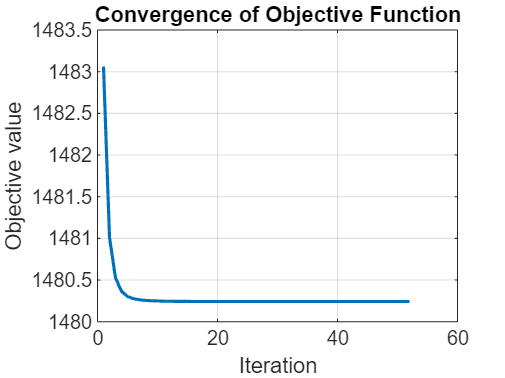

    [m, n] = size(A);
    z0= zeros(n, 1);
    u0 = zeros(n, 1);
    AtA = A'*A;
    Atb = A'*b;
    i=1;

    history.objval = zeros(max_iter,1);

    history.primal_res = zeros(max_iter,1);
    history.dual_res = zeros(max_iter,1);
    while i<max_iter
        x1 = inv(AtA + rho*eye(n))*(Atb + rho*(z0 - u0));
        z1 = rho*(x1+u0)/(2*lambda + rho);

RMSE: 0.72156


        u1 = u0 + (x1 - z1);

MAE: 0.38964



        r_norm = norm(x1 - z1);
        s_norm = norm(rho*(z1-z0));

        history.objval(i) = 0.5*norm(A*x1-b)^2 + lambda*norm(z1,2)^2;
        history.primal_res(i) = r_norm;
        history.dual_res(i) = s_norm;


cvx_status = 'Solved'

        if (r_norm <= tol && s_norm <=tol)
            fprintf("Converged at %dth iteration",i)
            history.objval = history.objval(1:i);
            history.primal_res = history.primal_res(1:i);
            history.dual_res = history.dual_res(1:i);

RMSE: 0.54952


            break

MAE: 0.33649


        end
        z0 = z1;
        u0 = u1;
        i=i+1;
    end
    x= x1;
end
[x,history]= ridge_admm(A_train,b_train,lambda,rho,max_iter,tol);


figure;
plot(history.objval, 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('Objective value');
title('Convergence of Objective Function');
grid on;

y = A_test * x;
rmse = sqrt(mean((y - b_test).^2));
mae = mean(abs(y - b_test));
disp(['RMSE: ', num2str(rmse)]);
disp(['MAE: ', num2str(mae)]);

[~,n] = size(A);
cvx_clear
cvx_begin quiet
    variables w(n)
    minimize(0.5*sum_square(A*w - b) + 0.5*lambda*sum_square(w))
cvx_end
cvx_status

yaa = A_test*w;
rmse = sqrt(mean((yaa - b_test).^2));
mae = mean(abs(yaa - b_test));
disp(['RMSE: ', num2str(rmse)]);
disp(['MAE: ', num2str(mae)]);